# RESULT: Arm Design Comparison

*MATLAB Version:*

version

ans = '24.1.0.2689473 (R2024a) Update 6'

*Last revised:*

date

ans = '14-Sep-2024'

color_gray = [150 150 150] / 255;
color_light_gray = [175, 175, 175] / 255;

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_green];

% Lighter colors
color_light_green = [130 205 174] / 255;
color_light_yellow = [248 203 97] / 255;
color_light_blue = [135 167 250] / 255;
color_light_red = [230 100 164] / 255;

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_green];

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.50;

p_bounds = [50; 100; 100; 50];

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;
struct_design.p_bounds = p_bounds;

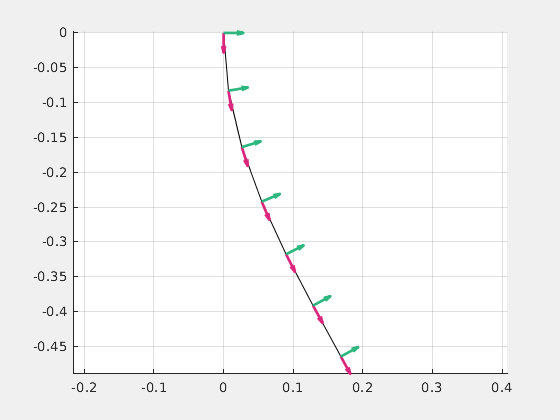

% Define the target shape
a = -1;
b = 1;

l = 0.5;

s = linspace(0, 1, N_nodes);
segment_twists = [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];


% Naively find the pressure which gets the arm closest to the target pose

poses = calc_poses(g_0, segment_twists);

ax = axes(figure());
plot_poses(poses, ax);
grid on
set(gcf, "visible", true)

% Compute reaction wrench requirement from a given tip load
tip_load = [0; -10; 0];
w_external = calc_external_wrench(segment_twists, tip_load, g_0);
a_requirement = -w_external;
[req_af, req_am] = mat_wrenches_to_traces(a_requirement);
rltv_req_af = req_af - req_af(1);
rltv_req_am = req_am - req_am(1);

% Sample pressures
N_p_sample = 150;
p_interior = diag(struct_design.p_bounds) * betarnd(0.3, 0.3, 4, N_p_sample);

[interior_af, interior_am] = compute_reaction_traces(p_interior, segment_twists, struct_design);
interior_rltv_af = interior_af - interior_af(1, :);
interior_rltv_am = interior_am - interior_am(1, :);

% Sample boundary pressures and compute their corresponding wrench space
% metrics
p_bndry = sample_edges_of_cuboid(3, struct_design.p_bounds);
[bndry_af, bndry_am] = compute_attainable_wrench_space(segment_twists, struct_design);
[cell_afs, cell_ams] = relative_attainable_wrench_hull(bndry_af, bndry_am);

i_bndry = boundary(bndry_af(1, :)', bndry_am(1, :)', 0);
bndry_af_ordered= bndry_af(:, i_bndry);
bndry_am_ordered = bndry_am(:, i_bndry);

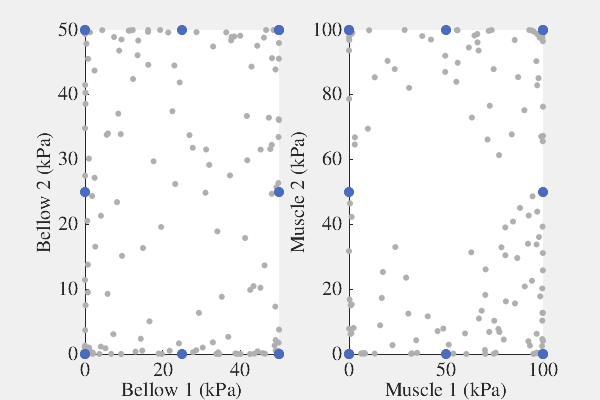

figure("Position", [0, 0, 600, 400])
subplot(1, 2, 1);
hold on
scatter(p_interior(1, :), p_interior(4, :), 20, color_light_gray, "filled");
scatter(p_bndry(1, :), p_bndry(4, :), 50, color_dark_blue, "filled");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")
xlim([0, 50]);
ylim([0, 50]);

subplot(1, 2, 2);
hold on
scatter(p_interior(2, :), p_interior(3, :), 20, color_light_gray, "filled");
scatter(p_bndry(2, :), p_bndry(3, :), 50, color_dark_blue, "filled");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
xlim([0, 100]);
ylim([0, 100]);

set(gcf, "Visible", true)
fontname("nimbus roman")
fontsize(15, "points")

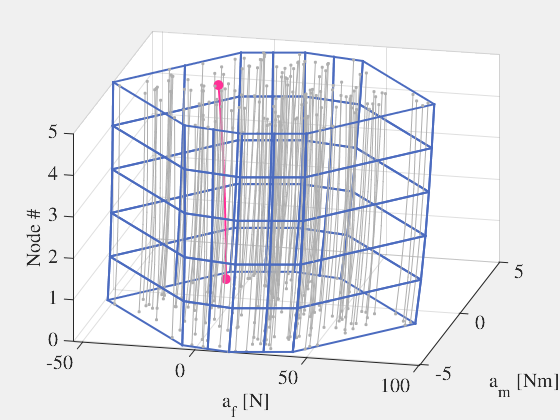

% Plot the wrench hulls. xlim([0, 50]);
ax = axes(figure("Visible", true));
hold on
plot_style = struct("facealpha", 0, "linewidth", 1.5, "edgecolor", color_dark_blue);
plot_wrench_hull(bndry_af_ordered, bndry_am_ordered, ax, color_blue, plot_style, (N_nodes-1));
plot3(interior_af', interior_am', s * (N_nodes-1), ".-", "color", color_light_gray, "markerindices", [1, N_nodes]);
plot3(req_af', req_am', s * (N_nodes - 1), ".-", "color", color_red, "markerindices", [1, N_nodes], "linewidth", 1.5, "markersize", 20);
view(13, 27)
grid on
xlabel("a_f [N]");
ylabel("a_m [Nm]");
zlabel("Node #");
fontname("nimbus roman")
fontsize(15, "points")

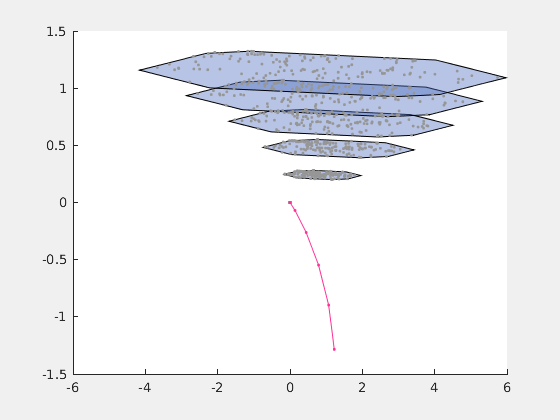

% Plot the relative wrench hull
ax = axes(figure("Visible", true));
hold on
rltv_bndry_af = bndry_af - bndry_af(1, :);
rltv_bndry_am = bndry_am - bndry_am(1, :);
for i = 2 : N_nodes
    i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);
    fill(ax, rltv_bndry_af(i, i_bndry), rltv_bndry_am(i, i_bndry), color_dark_blue, "facealpha", 0.4);
end
plot(interior_rltv_af, interior_rltv_am, ".", "color", color_gray);
plot(rltv_req_af, rltv_req_am, ".-", "color", color_red);

function [boundary_af, boundary_am] = compute_attainable_wrench_space(mat_segment_twists, struct_design)
    boundary_ps = sample_edges_of_cuboid(3, struct_design.p_bounds);
    [boundary_af, boundary_am] = compute_reaction_traces(boundary_ps, mat_segment_twists, struct_design);
end

function [cell_rltv_bndry_af_per_node, cell_rltv_bndry_am_per_node] = relative_attainable_wrench_hull(bndry_af, bndry_am)
    N_nodes = size(bndry_af, 1);

    cell_rltv_bndry_af_per_node = cell(1, N_nodes);
    cell_rltv_bndry_am_per_node = cell(1, N_nodes);

    cell_rltv_bndry_af_per_node{1} = [0, 0];
    cell_rltv_bndry_am_per_node{1} = [0, 0];

    % Compute all the relative attainble reaction traces
    % These points will form the boundary of the relatively attainable
    % reaction space for each node. 
    rltv_bndry_af = bndry_af - bndry_af(1, :);
    rltv_bndry_am = bndry_am - bndry_am(1, :);

    for i = 2 : N_nodes
        % Order the points for each node, and only keep the ones that
        % contribute to the convex hull
        i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);

        cell_rltv_bndry_af_per_node{i} = rltv_bndry_af(i, i_bndry);
        cell_rltv_bndry_am_per_node{i} = rltv_bndry_am(i, i_bndry);
    end
end